# Wave-Driven Desalination

Note: this example requires a properly set-up [WEC-Sim install](https://wec-sim.github.io/WEC-Sim/dev/user/getting_started.html) to work properly.

An excellent use case for this toolbox is in wave-driven desalination systems. These systems utilize mechanical energy captured in the motion of a Wave Energy Converter (WEC) to drive some sort of pump, directly pressurizing sea water to the pressures necessary for Sea Water Reverse Osmosis (SWRO), see [OsmoticPressure.m](matlab:open('..\..\OsmoticPressure.m')) example for more on SWRO. An example concept drawing of this system is shown below: 

In motion, this looks like:

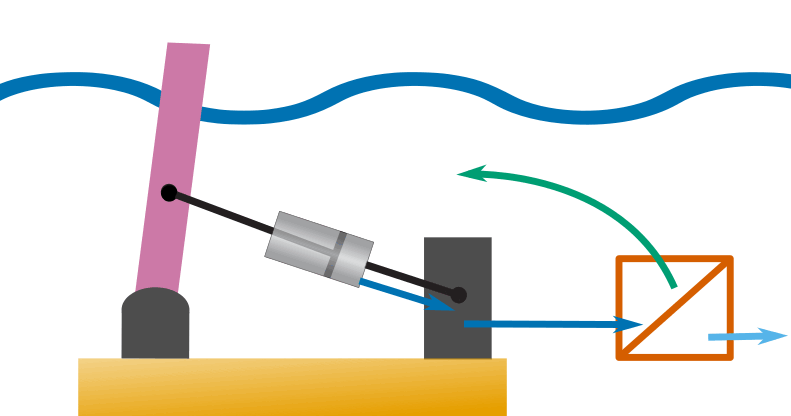

Now this is a significant simplification, in reality, we'd use a double acting piston to take advantage of the motion in both directions as well as an accumulator to smooth the feed flow, but this shows the basic idea. However, even with the accumulator, this system clearly does not run the SWRO membranes at steady state, and due to the high coupling between the WEC and SWRO systems, a fully coupled model that connects these two systems and simulates unsteady SWRO processes is required. This makes Simscape an excellent option, but only with this new toolbox.

## Basic SWRO Desalination Hydraulic Model

Before we involve WEC-Sim, lets first discuss the basic SWRO hydraulic model.

Take a minute to explore the [BasicDesalHydraulics.slx](matlab:open('.\BasicDesalHydraulics.slx')) model. There are a few main elements, first the hydraulic cylinder, which also contains directional valves to ensure water is taken in from the sea water source and sent out into the hydraulic circuit. You can see two versions of the hydraulic cylinder model. One with check valves, representing a more realistic depiction, and one with controlled area restrictions, with the area controlled by the sign of the velocity signal. These valves mimic the behavior of the check valves, but make things easier on the solver. There is also a gas charged accumulator which smooths the flow, a pressure relief valve to make sure the maximum pressure in the SWRO membrane is not exceeded, the membrane model itself, and finally a resistance on the brine flow which can be tuned to set the recovery ratio. This basic test model just represents the WEC motion with a sine wave, try out adjusting parameters to change the behavior of the flow rates, pressure, and concentratrations.

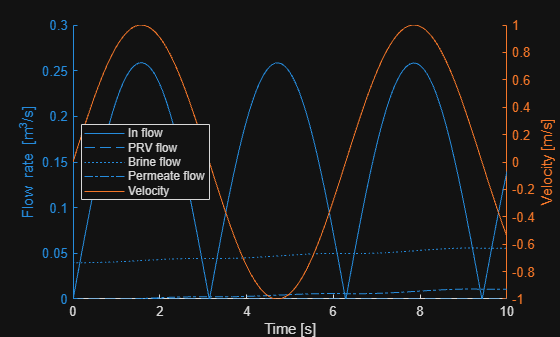

out1=sim("tBasicDesalHydraulics.slx");
t_v = out1.simout.Velocity.Time;
v_in =  out1.simout.Velocity.Data;
t = out1.simout.In_Flow.Time;
Q_in =  out1.simout.In_Flow.Data;
Q_perm = out1.simout.Perm_Flow.Data;
Q_brine = out1.simout.Brine_Flow.Data;
Q_PRV = out1.simout.PRV_Flow.Data;
figure('Name','Isolated PTO Flows')
yyaxis right
line(t_v,v_in,'DisplayName','Velocity')
ylabel('Velocity [m/s]')
yyaxis left
line(t,Q_in,'DisplayName','In flow')
line(t,Q_PRV,'DisplayName','PRV flow')
line(t,Q_brine,'DisplayName','Brine flow')
line(t,Q_perm,'DisplayName','Permeate flow')
ylabel('Flow rate [m^3/s]')
ylim([0,0.3])
xlabel('Time [s]')
legend('location','best')

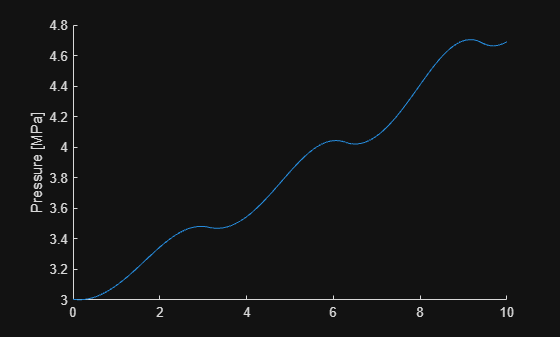

figure('Name','Isolated PTO Pressure')
line(t,out1.simout.Feed_Pressure.Data/1e6)
ylabel('Pressure [MPa]')

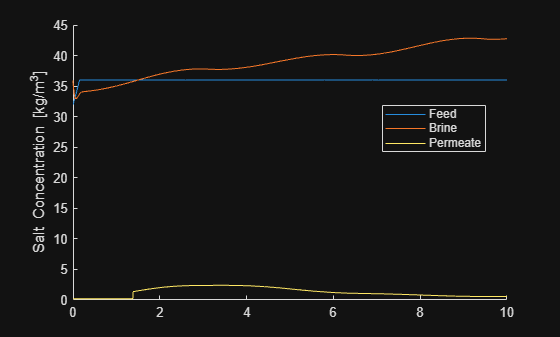

figure('Name','Isolated PTO Concentrations')
line(t,out1.simout.Feed_Concentration.Data,'DisplayName','Feed')
line(t,out1.simout.Brine_Concentration.Data,'DisplayName','Brine')
line(t,out1.simout.Perm_Concentration.Data,'DisplayName','Permeate')
ylabel('Salt Concentration [kg/m^3]')
legend('Location','best')

## Integration with WEC-Sim

While this dynamic simulation of SWRO is important, to truly understand the performance of a wave-driven desalination system we need to couple the simulation of the WEC dynamics and SWRO together. Convieniently WEC-Sim is built in Simulink, making it easy to connect a WEC model to a power take-off model built in Simscape. You'll need to give it some time to run though.

load_system('waveDrivenDesal.slx');
set_param('waveDrivenDesal/SWRO PTO', 'Commented', 'off');
set_param('waveDrivenDesal/SWRO PTO w// ERU', 'Commented', 'on');
close_system('waveDrivenDesal.slx',1)
wecSim

WEC-Sim: An open-source code for simulating wave energy converters
Version: 7.0.0

Initializing the Simulation Class...
	Case Dir: C:\Users\ndegoede\Projects\simscape_desal_internal 

WEC-Sim Pre-processing ...   
Elapsed time is 1.500216 seconds.

WEC-Sim Simulation Settings:
	Start Time                     (sec) = 0
	End Time                       (sec) = 60
	Time Step Size                 (sec) = 0.1
	Ramp Function Time             (sec) = 0
	Convolution Integral Interval  (sec) = 10
	 Number of Time Steps     = 600 

Wave Environment: 
	Wave Type                            = Irregular Waves (Predefined Random Phase)
	Spectrum Type                        = Pierson-Moskowitz  
	Significant Wave Height, Hs      (m) = 9.86
	Peak Wave Period, Tp           (sec) = 2.64

List of Body:
 
Number of Hydro Bodies = 2 

	***** Body Number 1, Name: flap *****
	Body CG                          (m) = [0,0,-3.9]
	Body Mass                       (kg) = 127000 
	Body Moments of Inertia       (kgm2) 

Elapsed time is 90.238039 seconds.

Post-processing and saving...   
Elapsed time is 0.229102 seconds.


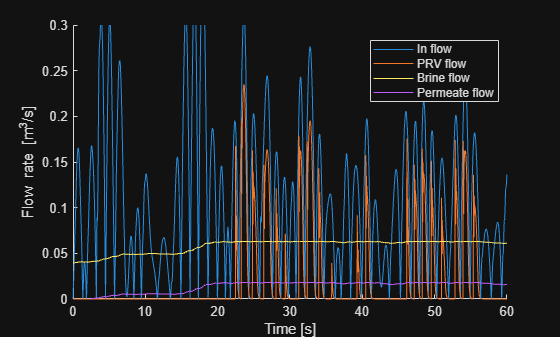

t_v = simout.Velocity.Time;
v_in =  simout.Velocity.Data;
t = simout.In_Flow.Time;
Q_in = simout.In_Flow.Data;
Q_perm = simout.Perm_Flow.Data;
Q_brine = simout.Brine_Flow.Data;
Q_PRV = simout.PRV_Flow.Data;
figure('Name','Flows')
%yyaxis right
%line(t_v,v_in,'DisplayName','Velocity')
%ylabel('Velocity [m/s]')
%yyaxis left
line(t,Q_in,'DisplayName','In flow')
line(t,Q_PRV,'DisplayName','PRV flow')
line(t,Q_brine,'DisplayName','Brine flow')
line(t,Q_perm,'DisplayName','Permeate flow')
ylabel('Flow rate [m^3/s]')
ylim([0,0.3])
%xlim([200,250])
xlabel('Time [s]')
legend('location','best')

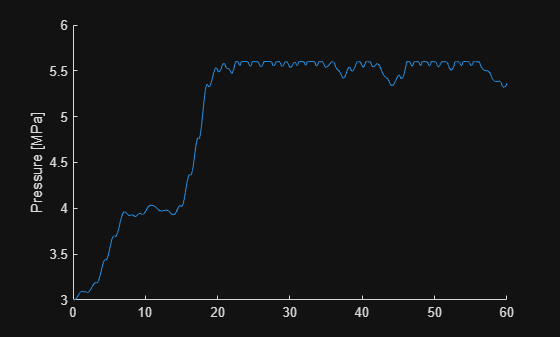

figure('Name','Pressure')
line(t,simout.Feed_Pressure.Data/1e6)
%xlim([200,250])
ylabel('Pressure [MPa]')

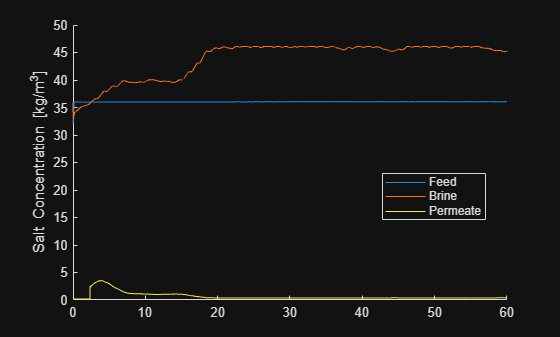

figure('Name','Concentrations')
line(t,simout.Feed_Concentration.Data,'DisplayName','Feed')
line(t,simout.Brine_Concentration.Data,'DisplayName','Brine')
line(t,simout.Perm_Concentration.Data,'DisplayName','Permeate')
ylabel('Salt Concentration [kg/m^3]')
%xlim([200,250])
legend('Location','best')

## Improving the Design

In our wave-driven desalination system, we have 3 main final energy states: directly used in desalination, brine waste, and excess that leaves the pressure relief valve. Let's plot the breakdown to see how muich of the energy entering the system actually ends up direcetly used in desalination.

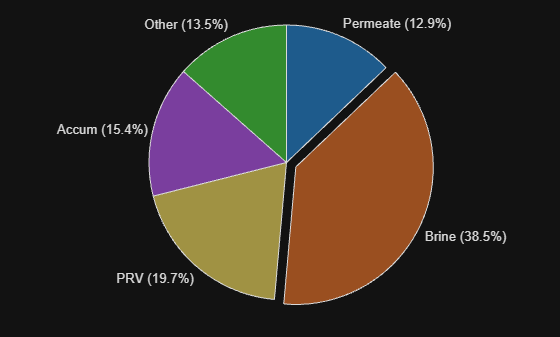

t = simout.In_Flow.Time;
E_in = trapz(t,simout.In_Flow.Data.*simout.Feed_Pressure.Data);
E_prv = trapz(t,simout.PRV_Flow.Data.*simout.Feed_Pressure.Data);
E_brine = trapz(t,simout.Brine_Flow.Data.*simout.Brine_Pressure.Data);
E_accum = trapz(t,simout.Accum_Flow.Data.*simout.Feed_Pressure.Data);
E_perm = trapz(t,simout.Perm_Flow.Data.*simout.Feed_Pressure.Data);
E_other = E_in - E_prv - E_brine - E_accum - E_perm;
figure('Name','basic energy')
energy = [E_perm,E_brine,E_prv,E_accum,E_other];
labels = {'Permeate','Brine','PRV','Accum','Other'};
piechart(energy,labels,ExplodedWedges=2)

The Brine flow contains a massive amount of energy, and unfortunately, just increasing the resistance on the brine stream isn't really an option as we need to keep our recovery ratio from being too high. Many SWRO desalination plants utilize energy recovery units (ERUs) to help with this. ERUs take energy from the brine flow and use it to pressurize more feed flow increasing overall efficiency. Try uncommenting the ERU PTO and comment out the basic one in the waveDrivenDesal model.

Then go back to the next section to re-run WEC-Sim.

load_system('waveDrivenDesal.slx');
set_param('waveDrivenDesal/SWRO PTO', 'Commented', 'on');
set_param('waveDrivenDesal/SWRO PTO w// ERU', 'Commented', 'off');
close_system('waveDrivenDesal.slx',1)
wecSim

WEC-Sim: An open-source code for simulating wave energy converters
Version: 7.0.0

Initializing the Simulation Class...
	Case Dir: C:\Users\ndegoede\Projects\simscape_desal_internal 

WEC-Sim Pre-processing ...   
Elapsed time is 0.958802 seconds.

WEC-Sim Simulation Settings:
	Start Time                     (sec) = 0
	End Time                       (sec) = 60
	Time Step Size                 (sec) = 0.1
	Ramp Function Time             (sec) = 0
	Convolution Integral Interval  (sec) = 10
	 Number of Time Steps     = 600 

Wave Environment: 
	Wave Type                            = Irregular Waves (Predefined Random Phase)
	Spectrum Type                        = Pierson-Moskowitz  
	Significant Wave Height, Hs      (m) = 9.86
	Peak Wave Period, Tp           (sec) = 2.64

List of Body:
 
Number of Hydro Bodies = 2 

	***** Body Number 1, Name: flap *****
	Body CG                          (m) = [0,0,-3.9]
	Body Mass                       (kg) = 127000 
	Body Moments of Inertia       (kgm2) 

Elapsed time is 86.533648 seconds.

Post-processing and saving...   
Elapsed time is 0.231947 seconds.


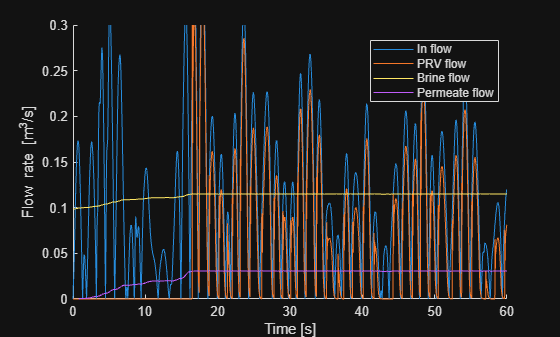

t_v = simout1.Velocity.Time;
v_in =  simout1.Velocity.Data;
t = simout1.In_Flow.Time;
Q_in = simout1.In_Flow.Data;
Q_perm = simout1.Perm_Flow.Data;
Q_brine = simout1.Brine_Flow.Data;
Q_PRV = simout1.PRV_Flow.Data;
figure('Name','Flows')
%yyaxis right
%line(t_v,v_in,'DisplayName','Velocity')
%ylabel('Velocity [m/s]')
%yyaxis left
line(t,Q_in,'DisplayName','In flow')
line(t,Q_PRV,'DisplayName','PRV flow')
line(t,Q_brine,'DisplayName','Brine flow')
line(t,Q_perm,'DisplayName','Permeate flow')
ylabel('Flow rate [m^3/s]')
ylim([0,0.3])
%xlim([200,250])
xlabel('Time [s]')
legend('location','best')

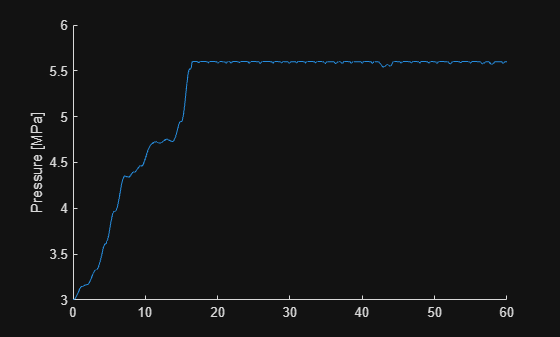

figure('Name','Pressure')
line(t,simout1.Feed_Pressure.Data/1e6)
%xlim([200,250])
ylabel('Pressure [MPa]')

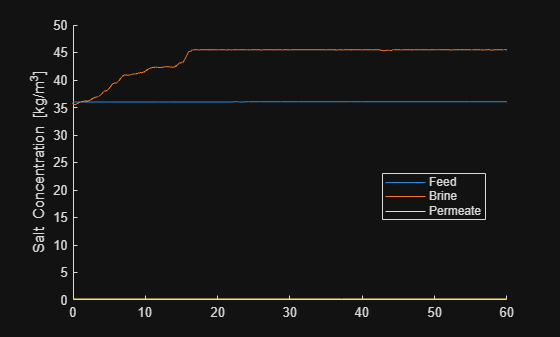

figure('Name','Concentrations')
line(t,simout1.Feed_Concentration.Data,'DisplayName','Feed')
line(t,simout1.Brine_Concentration.Data,'DisplayName','Brine')
line(t,simout1.Perm_Concentration.Data,'DisplayName','Permeate')
ylabel('Salt Concentration [kg/m^3]')
%xlim([200,250])
legend('Location','best')

## ERU Energy Usage

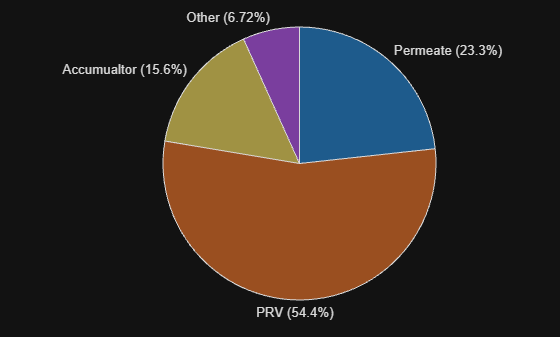

t = simout1.ERU_Flow.Time;
E_in = trapz(t,simout1.In_Flow.Data.*simout1.Feed_Pressure.Data);
E_prv = trapz(t,simout1.PRV_Flow.Data.*simout1.Feed_Pressure.Data);
E_accum = trapz(t,simout1.Accum_Flow.Data.*simout1.Feed_Pressure.Data);
E_perm = trapz(t,simout1.Perm_Flow.Data.*simout1.Feed_Pressure.Data);
E_other = E_in - E_prv -E_accum - E_perm;
figure('Name','basic energy')
energy = [E_perm,E_prv,E_accum,E_other];
labels = {'Permeate','PRV','Accumualtor','Other'};
piechart(energy,labels)

Now the energy lost out the brine stream is much lower, but a larger plant would probably be optimal to reduce the amount lost out the PRV.